## Initizilation

clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);

T_kelvin = 293.1500

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);



## Filter

s=tf('s');
WZ = 1/10000000*eye(4)*(1)/(s+1);
param = model.calculateWz(param,WZ,1);
% figure()
% bode(WZ)
WW = 0.0001*eye(4)*1/(s+0.0001);
param = model.calculateWw(param,WW,1);

## Control

param = control.DesignProcedureRobustPerformanceAndRobustStability(param,1);

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.1379
       solvertime: 0.0245
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|        Matrix inequality|           0.70924|      5.8919e-11|
|   #2|        Matrix inequality|            0.3828|      5.0187e-11|
|   #3|        Matrix inequality|        -1.382e-10|      1.6931e-11|
|   #4|        Matrix inequality|            0.3828|      5.0187e-11|
|   #5|   Elementwise inequality|            1.0003|      1.1802e-10|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals. |
| In practice, many solvers converge to slightly infeasible         |
| solutions, which may cause some residuals to be negative.         |
| It is up to the user to judge the importance and impact of        |
| slightly negative residuals (i.e. infeasibilities)                |
| https://yalmip.g

ans = 1.0003

gamma robust stab


ans = NaN

Kfull =     5.1904    3.9777    2.7903         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    7.9756    1.0898    3.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    5.2464    2.5403    2.4388         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    5.4729    3.0947    2.6594         0         0         0         0         0         0         0         0         0         0         0         0
       NaN       NaN       N

k =     5.1904    3.9777    2.7903         0         0         0         0         0         0         0         0         0
         0         0         0    7.9756    1.0898    3.0148         0         0         0         0         0         0
         0         0         0         0         0         0    5.2464    2.5403    2.4388         0         0         0
         0         0         0         0         0         0         0         0         0    5.4729    3.0947    2.6594


Eig of Robust performance


ans =    -5.0531
   -4.9028
   -4.8638
   -4.5712
   -3.8225
   -3.1404
   -2.9523
   -2.7903
   -2.3547
   -2.3510


Eig of Q_hat


ans =     0.3828
    0.3836
    0.3881
    0.3895
    0.6935
    0.6957
    0.6964
    0.7031
    1.9581
    1.9581


## Verify robust stability

By calculating Mw and taking th    e Hinfnorm the robust stability can be verified 

Mw = model.calculateMw(param);

s =
 
  s
 
Continuous-time transfer function.
Model Properties


hinfnorm(Mw)

ans = 0.2431

### Calculate Nw

This is used to understand how the weights shape the bode plot and thereby the performance

Cz = -blkdiag([0 1 0],[0 1 0],[0 1 0],[0 1 0]);
Bw = -blkdiag([0;0;1],[0;0;1],[0;0;1],[0;0;1]);
Dz = eye(4);
A_hat = [param.model.A, zeros(12,4) Bw*param.model.Cww, zeros(12,4);
         zeros(4,12),param.model.Awd, zeros(4),zeros(4);
         zeros(4,12),zeros(4),param.model.Aww, zeros(4);
         param.model.Bwz*Cz, zeros(4),param.model.Bwz*Dz*param.model.Cww, param.model.Awz]; 

B_hat = [param.model.B, zeros(12,4),zeros(12,4),zeros(12,4);
         param.model.Bwd, zeros(4),zeros(4),zeros(4);
         zeros(4,16)
         zeros(4,16)];

B_bar = [param.model.B, Bw*param.model.Dww;
         zeros(4,4),zeros(4,4);
         zeros(4,4),param.model.Bww;
         zeros(4,4),param.model.Bwz*Dz*param.model.Dww];

C1 = [zeros(4,12), param.model.Cwd,zeros(4),zeros(4);
      param.model.Dwz*Cz , zeros(4), param.model.Dwz*Dz*param.model.Cww, param.model.Cwz];
C2 = [param.model.Dwd, zeros(4),zeros(4),zeros(4);
      zeros(4),zeros(4),zeros(4),zeros(4)];

D_Bar = [zeros(4),zeros(4);
         zeros(4), param.model.Bwz*Dz*param.model.Dww];

Mw = model.calculateMw(param);

s =
 
  s
 
Continuous-time transfer function.
Model Properties


K_hat = blkdiag(param.ctrl.K*param.model.Cy,eye(4),eye(4),eye(4));
N = (C1+C2*K_hat)/(s*eye(24)-(A_hat+B_hat*K_hat))*B_bar+D_Bar;



## Simulate The nonlinear system

0.000000, 0.000000, -17.303451, 0.000000, 


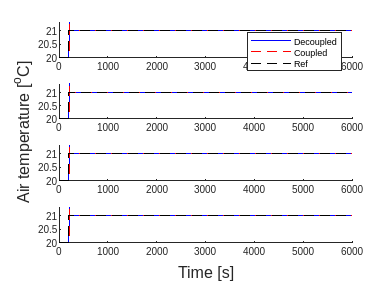

 util.SimulateStep(param,"TestPerAndStab",0);

## Obtain Ww and Wz 

- Simulate the system with feedforward Ww and Wz, determine the performance. Too aggresisve (overshoot).  Design Ww to be more costly for the current bandwith to affect the system.

-    WZ = 1/200*eye(4)*(s+20)/(s+1) 

-     WW = 1; 

-     fint respons 

- prøv med WW 

- WZ = 1 